# Hand Posture Recognition- K-means Clustering, experiment with various distance measures

## Load data

data_path = 'hand_posture.csv';
%dataset from https://archive.ics.uci.edu/ml/datasets/MoCap+Hand+Postures
hand_pos_data = readtable(data_path, 'TreatAsEmpty',{'?', ' ', '.','NA'});  
%clean the data; Replace the mentioned elements with NaN
%readtable handle all data types present in the table and retains the
%header too, hence it is better than readcsv and readxls

data = hand_pos_data(1:end, 3:20);  %78095     18
labels = hand_pos_data(1:end, 1);
disp(['Data ', num2str(size(data))])

Data 78095     18


disp(['Dataset consists of ',num2str(size(data,1)), ' samples and ',num2str(size(data,2)),' features '])

Dataset consists of 78095 samples and 18 features 


classes = unique(table2array(labels));
disp(['Classes in dataset: ',num2str(classes')]);

Classes in dataset: 1  2  3  4  5


feature_names = [];  %create a string array containing feature names
for i=1:width(data)
    x = data.Properties.VariableNames(i);
    feature_names = [feature_names, string(x{1})];
end
disp(['Features in data: ', feature_names])

  Columns 1 through 14

    "Features in data: "    "X0"    "Y0"    "Z0"    "X1"    "Y1"    "Z1"    "X2"    "Y2"    "Z2"    "X3"    "Y3"    "Z3"    "X4"

  Columns 15 through 19

    "Y4"    "Z4"    "X5"    "Y5"    "Z5"



## Data cleaning

dataset_array = table2dataset(data); %dataset arrays are arrays for statistical data

messy_data = dataset_array;
%Find samples with missing values
ix = ismissing(messy_data, 'StringTreatAsMissing', {'?',' ','NaN','.','NA'});
[rowIdcs, ~]  = find(sum(ix,2)~=0);
disp([num2str(length(rowIdcs)), ' obervations in total have missing values']); 

13023 obervations in total have missing values


disp(['These samples will be removed']);

These samples will be removed


%Create a dataset array with complete observations
%Create the new clean dataset that is = old data minus all missing
%obervations

ix = ismissing(messy_data);
cleaned_data = messy_data(~any(ix,2),:);
disp(['New cleaned data: ', num2str(size(cleaned_data))]);

New cleaned data: 65072     18


## Normalize data

X_norm = mapminmax(double(cleaned_data)')';  %later, we do PCA that needs data normalized along columns
disp(['Normalize data so that the max and min values in a column are -1 and +1']);

Normalize data so that the max and min values in a column are -1 and +1


disp(['Data min = ', num2str(min(X_norm(:))), ', max = ', num2str(max(X_norm(:)))]);

Data min = -1, max = 1


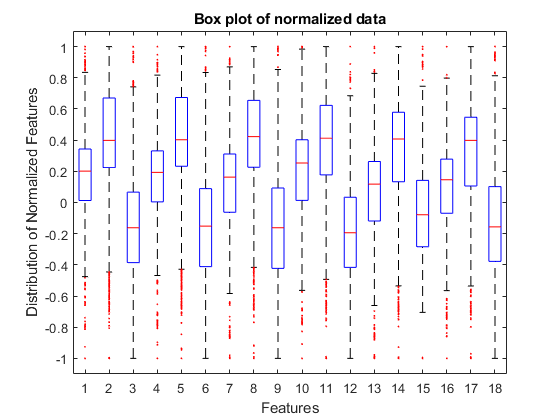

%% View and remove outliers
boxplot(X_norm, 'OutlierSize',1, 'Symbol', 'ro');
title('Box plot of normalized data');
xlabel('Features');
ylabel('Distribution of Normalized Features');

TF = isoutlier(X_norm, 'quartile');
%method is quartile => we eliminate outliers that lie above or below 1.5* IQR(interquartile range = 50 percentitle = Q3-Q1)_
sum_TF = sum(TF,2);  
%sum TF row wise to find samples with outliers; array containing 1 corresponding to samples with outliers
nt_outlier_idx = find(sum_TF == 0);
outlier_idx = find(sum_TF ~= 0);
disp(['Data consists of ', num2str(length(outlier_idx)), ' outliers.']);

Data consists of 611 outliers.


X_outliers_rmvd = X_norm(nt_outlier_idx, :);
disp(['Data after outlier removal: ', num2str(size(X_outliers_rmvd))]);

Data after outlier removal: 64461     18


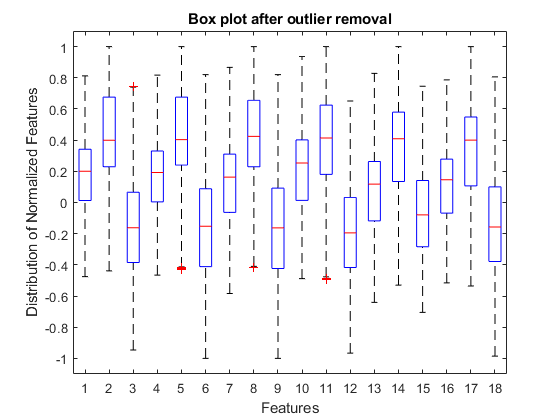

boxplot(X_outliers_rmvd);
title('Box plot after outlier removal');
xlabel('Features');
ylabel('Distribution of Normalized Features');

## Elbow plot to find optimum number of principal components

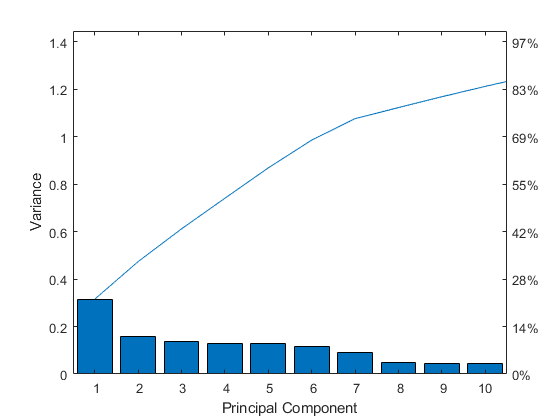

[loadings, X_pca_, variances, tscores] = pca(X_outliers_rmvd);
figure;
pareto(variances);
xlabel('Principal Component')
ylabel('Variance')

## K-means Clustering, k = 5

% 1. Squared euclidean distance

n_clusters = 5;
dist_measure = 'sqeuclidean';
n_comp = 2;
X_pca = X_pca_(:, 1:n_comp);
disp(['Data after PCA: ', num2str(size(X_pca))]);

Data after PCA: 64461      2


[cent_indices, cent_locations] = kmeans(X_pca, n_clusters, 'display', 'iter', 'dist', dist_measure); 

  iter	 phase	     num	         sum
     1	     1	   64461	     9719.06
     2	     1	    7833	     8582.21
     3	     1	    5985	     7959.74
     4	     1	    4897	     7548.41
     5	     1	    3802	     7277.14
     6	     1	    3027	     7102.67
     7	     1	    2178	     7016.41
     8	     1	    1437	     6979.57
     9	     1	     933	     6963.78
    10	     1	     574	     6957.61
    11	     1	     375	     6954.98
    12	     1	     243	     6953.87
    13	     1	     171	     6953.37
    14	     1	     120	     6953.09
    15	     1	      86	     6952.94
    16	     1	      53	     6952.88
    17	     1	      35	     6952.85
    18	     1	      31	     6952.83
    19	     1	      27	     6952.82
    20	     1	      18	     6952.81
    21	     1	       9	     6952.81
    22	     1	       9	      6952.8
    23	     1	       2	      6952.8
    24	     1	       2	      6952.8
    25	     1	       2	      6952.8
Best total sum of distances = 6952.8


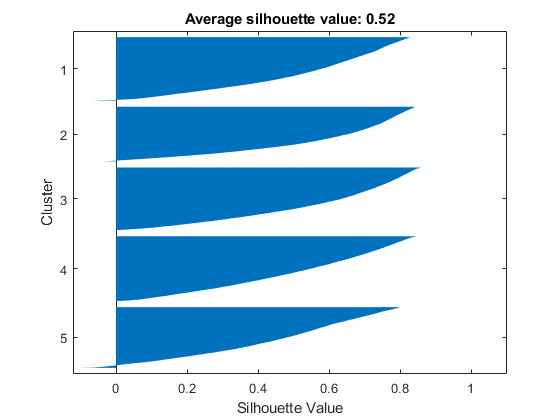

[sil_value,h] = silhouette(X_pca, cent_indices, dist_measure);
title(sprintf('Average silhouette value: %0.2f', mean(sil_value)))

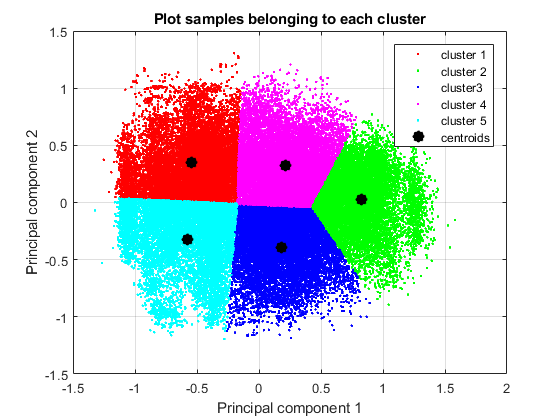

ptsymb = {'r.', 'g.', 'b.', 'm.', 'c.'};
for i = 1:n_clusters
    cluster = find(cent_indices==i);
    plot(X_pca(cluster,1),X_pca(cluster,2),ptsymb{i});
    hold on
end

plot(cent_locations(:,1), cent_locations(:,2),'*k','LineWidth', 7);
title('Plot samples belonging to each cluster')
hold off
xlabel('Principal component 1');
ylabel('Principal component 2');
legend('cluster 1','cluster 2', 'cluster3', 'cluster 4', 'cluster 5', 'centroids')
grid on

%2. cityblock distance 

dist_measure = 'cityblock';
n_clusters = 5;
n_comp = 2;

X_pca = X_pca_(:, 1:n_comp);
disp(['Data after PCA: ', num2str(size(X_pca))]);

Data after PCA: 64461      2


[cent_indices, cent_locations] = kmeans(X_pca, n_clusters, 'display', 'iter', 'dist', dist_measure);

  iter	 phase	     num	         sum
     1	     1	   64461	     26324.3
     2	     1	    8698	     25134.8
     3	     1	    3140	     24940.1
     4	     1	    1986	     24834.7
     5	     1	    1625	     24758.7
     6	     1	    1408	     24703.4
     7	     1	    1211	     24663.9
     8	     1	    1073	       24631
     9	     1	    1020	     24600.3
    10	     1	     925	     24573.4
    11	     1	     874	     24550.3
    12	     1	     880	     24527.5
    13	     1	     842	     24506.2
    14	     1	     752	     24486.8
    15	     1	     788	     24467.2
    16	     1	     761	     24451.2
    17	     1	     666	     24439.2
    18	     1	     567	     24428.7
    19	     1	     542	     24418.6
    20	     1	     572	     24407.9
    21	     1	     579	     24397.6
    22	     1	     587	     24387.4
    23	     1	     615	     24376.6
    24	     1	     583	     24366.3
    25	     1	     558	     24357.2
    26	     1	     533	     24348.8
    27	     1	     510	     

Best total sum of distances = 24093.3


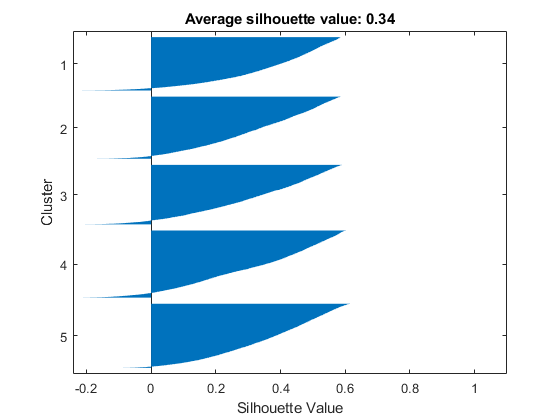

[sil_value,h] = silhouette(X_pca, cent_indices, dist_measure);
title(sprintf('Average silhouette value: %0.2f', mean(sil_value)))

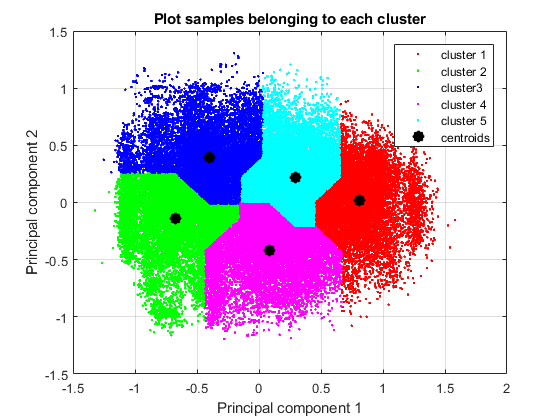

ptsymb = {'r.', 'g.', 'b.', 'm.', 'c.'};
for i = 1:n_clusters
    cluster = find(cent_indices==i);
    plot(X_pca(cluster,1),X_pca(cluster,2),ptsymb{i});
    hold on
end

plot(cent_locations(:,1), cent_locations(:,2),'*k','LineWidth', 7);
title('Plot samples belonging to each cluster')
hold off
xlabel('Principal component 1');
ylabel('Principal component 2');
legend('cluster 1','cluster 2', 'cluster3', 'cluster 4', 'cluster 5', 'centroids')
grid on

%3. cosine distance

dist_measure = 'cosine';
n_clusters = 5;
n_comp = 2;

X_pca = X_pca_(:, 1:n_comp);
disp(['Data after PCA: ', num2str(size(X_pca))]);

Data after PCA: 64461      2


[cent_indices, cent_locations] = kmeans(X_pca, n_clusters, 'display', 'iter', 'dist', dist_measure);

  iter	 phase	     num	         sum
     1	     1	   64461	     4672.27
     2	     1	    3247	      4408.7
     3	     1	    2177	     4279.33
     4	     1	    1817	     4199.57
     5	     1	    1488	     4148.13
     6	     1	    1195	     4114.51
     7	     1	     994	     4091.69
     8	     1	     893	     4074.45
     9	     1	     773	     4061.22
    10	     1	     673	     4049.56
    11	     1	     567	     4039.96
    12	     1	     501	     4031.56
    13	     1	     430	     4025.98
    14	     1	     423	     4021.49
    15	     1	     405	     4017.65
    16	     1	     381	     4014.32
    17	     1	     348	     4011.49
    18	     1	     402	     4008.05
    19	     1	     417	        4004
    20	     1	     436	     3999.57
    21	     1	     468	     3994.63
    22	     1	     451	     3989.78
    23	     1	     471	      3984.7
    24	     1	     488	      3979.3
    25	     1	     514	     3973.09
    26	     1	     531	     3966.36
    27	     1	     551	     

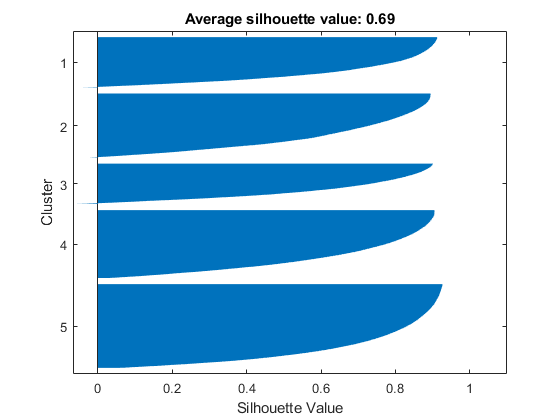

[sil_value,h] = silhouette(X_pca, cent_indices, dist_measure);
title(sprintf('Average silhouette value: %0.2f', mean(sil_value)))

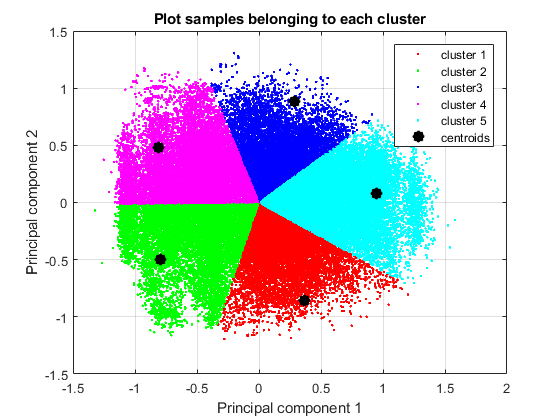

ptsymb = {'r.', 'g.', 'b.', 'm.', 'c.'};
for i = 1:n_clusters
    cluster = find(cent_indices==i);
    plot(X_pca(cluster,1),X_pca(cluster,2),ptsymb{i});
    hold on
end

plot(cent_locations(:,1), cent_locations(:,2),'*k','LineWidth', 7);
title('Plot samples belonging to each cluster')
hold off
xlabel('Principal component 1');
ylabel('Principal component 2');
legend('cluster 1','cluster 2', 'cluster3', 'cluster 4', 'cluster 5', 'centroids')
grid on